Demo code for Figure 2 of Idesis (2022) - Edge centric analysis of stroke patients. An alternative approach for biomarkers of lesion recovery

Edge-centric code adapted from Faskowitz, J. et al (2020) and Zamani Esfahalani (2020)

Adapted by: Sebastian Idesis - sebastian.idesis@upf.edu (Feb 2022)

Initialize script

clear all;close all;clc; %Close everything
nodes = 200; % Amount of nodes from the dataset
Isubdiag = find(tril(ones(nodes),-1)); %Upper triangle indexes needed later for PCA analysis

Add helper functions and data to path

addpath('Functions');
addpath('Data');
addpath('Functions\Violinplot-Matlab-master');

Load regional time series

load data/ts.mat %Demo data (Taken from https://www.brainnetworkslab.com/coderesources)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%PCA CALCULATION %%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

1a) Create fake data of other 4 control subjects and get correlation matrix

amount_of_controls= 5; %Number for control subjects for demo
for subj = 1:amount_of_controls
    ts_controls(:,:,subj)= ts.*(randn(1200,200)); %original ts plus a small factor random amount to make every subject different
    matrix_controls(:,:,subj) = corrcoef(ts_controls(:,:,subj)); %Calculate correlation matrix for each control subject
end

1b) Obtain average and standard deviation of control patients

avg_control= nanmean(matrix_controls,3); %average matrix of all control subjects
std_control= nanstd(matrix_controls,[],3); %standard deviation matrix of all control subjects

1c) Z-score controls matrices

matrix_for_pca_controls = zeros(amount_of_controls,length(Isubdiag)); %Preallocate variable
for subj = 1:amount_of_controls
    temp_matrix(:,:)=matrix_controls(:,:,subj); %Locate data in a temporary matrix to apply z-scoring
    z_scored_matrices_control= (temp_matrix - avg_control)./std_control; %Z-scored with controls mean and SD
    matrix_to_take_upper_part = z_scored_matrices_control; %Locate data in a temporary matrix to get upper triangle vector
    matrix_for_pca_controls(subj,:) = matrix_to_take_upper_part(Isubdiag); %vector of containing the upper triangle of each z-scored control subject
end

1d) Create fake data of 5 stroke patients and get correlation matrix

amount_of_patients= 5; %Number for demo
for subj = 1:amount_of_patients
    ts_patients(:,:,subj)= ts.*(randn(1200,200)*4); %original ts plus a bigger factor random amount to make every subject different
    matrix_patients(:,:,subj) = corrcoef(ts_patients(:,:,subj)); %Calculate correlation matrix for each patient
end

1e) Z-score patients matrices

matrix_for_pca_patients = zeros(amount_of_patients,length(Isubdiag)); %Preallocate variable
for subj = 1:amount_of_patients
    temp_matrix(:,:)=matrix_patients(:,:,subj); %Locate data in a temporary matrix to apply z-scoring
    z_scored_matrices_patients = (temp_matrix - avg_control)./std_control; %Z-scored with controls mean and SD
    matrix_to_take_upper_part = z_scored_matrices_patients; %Locate data in a temporary matrix to get upper triangle vector
    matrix_for_pca_patients(subj,:) = matrix_to_take_upper_part(Isubdiag); %vector of containing the upper triangle of each z-scored control subject
end

1f) Spatial PCA for patients (This is for 1 time, replicate previous steps for other time points)

X= matrix_for_pca_patients; %Define matrix to be used (subjects x upper-triangle data points)
X(isinf(X))=0; X(isnan(X))=0; %Check that there are not infinite or nan values
[~,score,~,~,explained] = pca(X); %Calculate PCA
explained_patients=explained(1:3) %Show how much variance is explained in each of the top 3 Components

explained_patients =    26.7062
   25.1038
   24.5301


pc_patients=score(:,1); %Store the first PC for each patient

%%% REPEAT THESE STEPS (1d-f) FOR EACH TIME POINT NEEDED %%%

Remove variables that wont be needed anymore

clear subj z_scored_matrices_patients z_scored_matrices_control matrix_to_take_upper_part

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%ENTROPY CALCULATION %%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Load data for entropy calculation - Patients

ts_patients_entropy=[]; % initialize variable
for subj = 1:amount_of_patients 
    ts_toload_patients = zscore(ts_patients(:,:,subj)); %z-score time series of each subject
    ts_patients_entropy = [ts_patients_entropy ts_toload_patients'];  %accumulate all the time series for next analysis
end

Entropy calculation - Patients

% create edge time series from regional time series
ts_patients_entropy = ts_patients_entropy';
[T_patients,N_patients] = size(ts_patients_entropy);
M_patients = N_patients*(N_patients - 1)/2; 
ets_patients = fcn_edgets(ts_patients_entropy,1); % this step does the z-scoring and element-wise products. the output is a [time x edge] matrix.
% run kmeans -- note that in principle any clustering algorithm can be
% applied to edge time series or the efc matrix
k = 10; 
ci_patients= kmeans(ets_patients',k,...
    'distance','sqeuclidean',...
    'maxiter',1000);
% map edge communities into matrix
mat_patients = zeros(N_patients);
mat_patients(triu(ones(N_patients),1) > 0) = ci_patients; % this step gives you the indices of each edge
mat_patients = mat_patients + mat_patients';

%% calculate normalized entropy
[u_patients,v_patients] = find(triu(ones(N_patients),1)); % this step gives you the indices of each edge
[~,enorm_patients] = fcn_node_entropy(ci_patients,u_patients,v_patients,N_patients);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%High amplitude co-fluctuations%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

High amplitude - Patients

for i = 1:5
    ts = ts_patients(:,:,i);
    ts = zscore(ts); % z-score time series
    [ntime,nnodes] = size(ts); % get dimensions
    nedges = nnodes*(nnodes - 1)/2; % calculate number of edges
    [u,v] = find(triu(ones(nnodes),1)); % indices of unique edges (upper triangle)
    idx = (v - 1)*nnodes + u;
    fc = corr(ts); %% calculate static fc
    ets = ts(:,u).*ts(:,v); %% generate edge time series
    fc_upper_triangle = fc(idx);
    rms = sum(ets.^2,2).^0.5; % calculate co-fluctuation amplitude at each frame
    frackeep = 0.1; % fraction of high- and low-amplitude frames to retain
    nkeep = round(ntime*frackeep);
    [~,idxsort] = sort(rms,'descend'); % sort co-fluctuation amplitude
    fctop = corr(ts(idxsort(1:nkeep),:)); % estimate fc using just high-amplitude frames
    fcbot = corr(ts(idxsort(end - nkeep + 1:end),:)); % do the same using just low-amplitude
    corr_top_patients(i)=corr(fctop(idx),fc(idx)); %correlation of top 10% with the whole FC matrix
    corr_top_patients(i)=corr(fcbot(idx),fc(idx)); %correlation of bottom 10% with the whole FC matrix
    %% calculate modularity of high-/low-amplitude fc
    numiter = 100; 
    qtop = zeros(numiter,1); qbot = qtop;
    for iter = 1:numiter
       [~,qtop(iter)] = community_louvain(fctop,[],[],'negative_asym');
       [~,qbot(iter)] = community_louvain(fcbot,[],[],'negative_asym');
    end
    qtop_3d(i,:) = qtop;
    qbot_3d(i,:) = qbot;
    %fprintf('Subject: %d done\n',i) %Uncomment if there are many subjects
    %in order to keep track of progress
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%Visualization%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Make figures to visualize

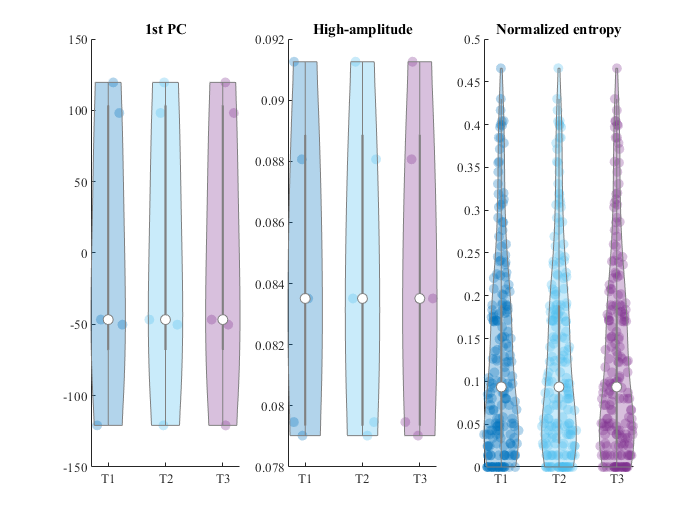

figure()

group = [zeros(1,length(corr_top_patients)),...
    ones(1,length(corr_top_patients)),...
    (ones(1,length(corr_top_patients))*2)]; %Create groups for violin plot

subplot(131)
temp_combined = [pc_patients' pc_patients' pc_patients']; %Replace the second and third variable with the corresponding time-point variable
vs = violinplot(temp_combined, group); %Plot violin
xticklabels({'T1','T2','T3'}); a = get(gca,'XTickLabel'); set(gca,'XTickLabel',a,'FontName','Times','fontsize',8);
title('1st PC')


subplot(132)
temp_combined = [corr_top_patients' corr_top_patients' corr_top_patients']; %Replace the second and third variable with the corresponding time-point variable
vs = violinplot(temp_combined, group);
xticklabels({'T1','T2','T3'}); a = get(gca,'XTickLabel'); set(gca,'XTickLabel',a,'FontName','Times','fontsize',8)
title('High-amplitude')

group = [zeros(1,length(enorm_patients)),...
    ones(1,length(enorm_patients)),...
    (ones(1,length(enorm_patients))*2)]; %Create groups for violin plot

subplot(133)
temp_combined = [enorm_patients' enorm_patients' enorm_patients']; %Replace the second and third variable with the corresponding time-point variable
vs = violinplot(temp_combined, group);
xticklabels({'T1','T2','T3'}); a = get(gca,'XTickLabel'); set(gca,'XTickLabel',a,'FontName','Times','fontsize',8)
title('Normalized entropy')